# Description

this code simulates a scenario. 

## desktop version

addpath('C:\Users\JBS\Documents\GitHub\path_planinng\ASAP1','C:\Users\JBS\Documents\GitHub\path_planinng\multi_target_tracking\','C:\Users\JBS\Documents\GitHub\path_planinng\plotregion\');
addpath('..\STOMP\')

## laptop version

addpath('C:\Users\junbs\Documents\path_planinng\ASAP1','C:\Users\junbs\Documents\path_planinng\multi_target_tracking\','C:\Users\junbs\Documents\path_planinng\plotregion\');

## Map setting in 2D projection space

map_dim = 20;
lx = 10; ly = 10; % size of map in real coordinate 
res = lx / map_dim;
% custom_map=makemap(20); % draw obstacle interactively
load('problem_settings.mat')

## Generate map occupancy grid object and path of the two targets

map = robotics.OccupancyGrid(flipud(custom_map),1/res);

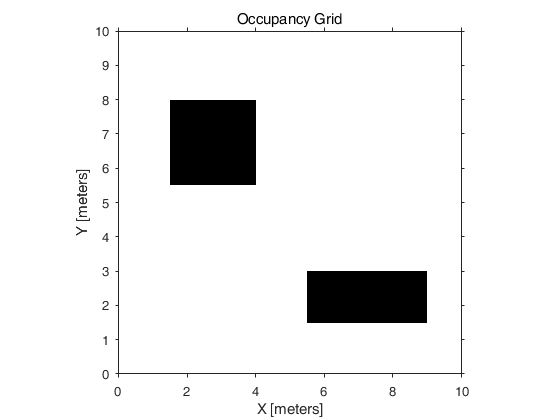

show(map);

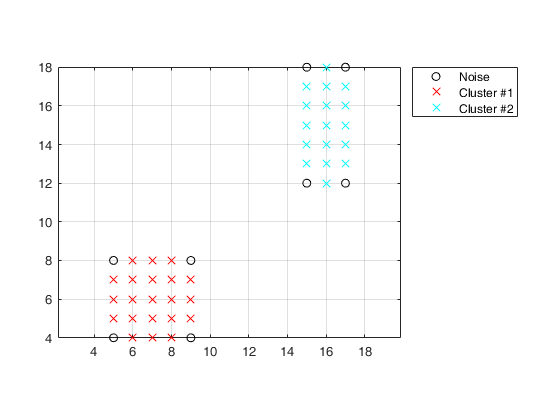

% [target1_xs,target1_ys,target2_xs,target2_ys,tracker]=set_target_tracker2; % assign path of two targets and tracker

% packing the target paths (should be same length)
% targets_xs = [target1_xs ; target2_xs];
% targets_ys = [target1_ys ; target2_ys];

% Clustering and give height for each obstacle 
epsilon=1; % neihbor hood bound 
MinPts=5; % minimum grouping index 
[occ_rows,occ_cols] = find(map.occupancyMatrix >= map.OccupiedThreshold);
occ_cells= [occ_rows occ_cols];
IDX=DBSCAN(occ_cells,epsilon,MinPts);
figure
PlotClusterinResult(occ_cells,IDX)

heights = [3,2];

% construct 3D map from 2D ground plan 
map3 = robotics.OccupancyMap3D(map.Resolution);

pcl = []; % should be N x 3
for idx = 1:max(IDX)
    xy_pnts=map.grid2world(occ_cells(find(IDX==idx),:));
    pcl_origin_pose = [ 0 0 0  0 0  0 1];

              
end











N_target = 2; % only two targets will be considered
target1_xs = targets_xs(1,:); target1_ys = targets_ys(1,:);
target2_xs  = targets_xs(2,:); target2_ys = targets_ys(2,:);

vis_cost_sets = {};

## Get score maps of each target during a prediction horizon

d_ref = 2;
N_azim_set = [10,10];
for n = 1:N_target 
    target_xs = targets_xs(n,:);
    target_ys = targets_ys(n,:);
    
    vis_cost_set = []; % row : time / col : angle index 
    N_azim = N_azim_set(n);
    DT_set = [];
    for t = 1:length(target_xs) % -1 is due to some mistake in set_target_tracker function 
        target_position = [target_xs(t), target_ys(t) 0]';
        
        ray_len = norm(target_position(1:2) - tracker); % should decide this length 
        ray_len = d_ref;
        ray_lens = ray_len * ones(N_azim,1); 
        angles = linspace(0,2*pi,N_azim+1);
        angles(end) = [];
        
        cast_res = zeros(1,N_azim); % 1 for hit and 0 for free rays   
        
        
        % inter occlusion prevention 
        if n == 1 % other agent will be 2
            other_agent_loc = [targets_xs(2,t) targets_ys(2,t)];
        else % other agent will be 1            
            other_agent_loc = [targets_xs(1,t) targets_ys(1,t)];
        end
        map_h = copy(map);

        % should do this twice 
        map_h.updateOccupancy(other_agent_loc,1);
        map_h.updateOccupancy(other_agent_loc,1);

        move_x = [-1,0,1];
        move_y = [-1,0,1];
        
        % for clarity, we should inflate the occupancy around the other (but too conservative)
        % agent 
%         
%         for i = 1:3
%             for j = 1:3
%                 other_agent_loc_around = other_agent_loc + res * [move_x(i) move_y(j)];
%                  % should do this twice 
%                 map_h.updateOccupancy(other_agent_loc_around,1);
%                 map_h.updateOccupancy(other_agent_loc_around,1);
%             end
%         end
%         
                            
                
        collisionPts=map_h.rayIntersection(target_position,angles,ray_len); % the NaN elements are not hit, 
        collisionIdx=find(~isnan(collisionPts(:,1))); % collided index 
        cast_res(collisionIdx) = 1;

        DT = signed_distance_transform([cast_res cast_res cast_res]); % periodic distance transform         
        DT = DT(N_azim+1:2*N_azim);        
        DT_set = [DT_set ; DT ];    
        
       
        if sum(DT==inf) % in this case, no occlusion occurs
            vis_cost = zeros(1,N_azim);
            vis_cost_set(t,:) = vis_cost;
        else % some ray hits
            vis_cost = max(DT) - DT + 1;         
%             vis_cost_extended = [vis_cost vis_cost(1)];     
            vis_cost_set(t,:) = vis_cost;

            
%             for k = 1: N_azim
%                 if (vis_cost(k)==0 || vis_cost(k+1)==0 )
%                     vis_cost_set(t,k) = 1;             
%                 else
%                     vis_cost_set(t,k) = (vis_cost(k) + vis_cost(k+1))/2;    
%                 end
%                 
%             end
            
        end
                
    end
    % save for each agent 
    vis_cost_sets{n} = vis_cost_set;
    DT_sets{n} = DT_set;
    
end

## Phase1 : feasible region convex division for LP problem

% for now, the feasible region (search space) for solving discrete path is just rectangle
% (TODO: extension for general affine region)

H = length(target_xs);
x_range = 12;
y_range = 10;
feasible_domain_x = [tracker(1) - x_range/2 tracker(1) + x_range/2];
xl = feasible_domain_x(1);
xu = feasible_domain_x(2);
feasible_domain_y = [tracker(2) - y_range/2  tracker(2)  + y_range/2];
yl = feasible_domain_y(1);
yu = feasible_domain_y(2);

search_spec.x_dom = [xl,xu];
search_spec.y_dom = [yl yu];

% plot the problem 
show(map)
hold on 
plot(target1_xs,target1_ys,'r^-','LineWidth',2)
plot(target2_xs,target2_ys,'r^-','LineWidth',2)
plot(tracker(1),tracker(2),'mo','MarkerFaceColor','m')
patch([xl xu xu xl],[yl yl yu yu],'red','FaceAlpha',0.1)

color_set = {'g','b'};
visi_info_set = {};

% let's investigate inequality matrix for each time step 
for n = 1:N_target
    % target path 
    target_xs = targets_xs(n,:);
    target_ys = targets_ys(n,:);
    
    % A_sub, b_sub : inequality matrix of each sub division region (only available region)
    Nh = zeros(1,H); % we also invesigate number of available regions per each time step 
    angles = linspace(0,2*pi,N_azim_set(n)+1);
    S = []; % flattened visibility score for easy computation in optimization     
    S_h = {}; % sorted way, this structure has same order  
    A_sub  = {};
    b_sub = {};
    N_vis_show = 3; % shows N largest vis score 
    for h = 1:H
        Nk = 0; % initialize number of valid region
        for k = 1:N_azim_set(n)    
            % Bounding lines of the k th pizza segment !
            theta1 = 2*pi/N_azim_set(n) * (k-1);
            theta2 = 2*pi/N_azim_set(n) * (k);        
            v1 = [cos(theta1), sin(theta1)]'; 
            v2 = [cos(theta2) , sin(theta2)]'; 
            % If this holds, then one of the two line is in the box 
            if ( is_in_box(v1,[target_xs(h) ; target_ys(h)],[xl xu],[yl yu]) || is_in_box(v2,[target_xs(h) ; target_ys(h)],[xl xu],[yl yu]) )
                if(DT_sets{n}(h,k) && DT_sets{n}(h,min(k+1,N_azim_set(n)))) % occlusion and collision rejection
                    [A,b] = get_ineq_matrix([target_xs(h) ; target_ys(h)],v1,v2);        
                    Nk = Nk +1;
                    A_sub{h}{Nk} = A; b_sub{h}{Nk}=b; % inequality constraint                    
                    S=[S vis_cost_sets{n}(h,k)]; % visbiility cost of the region 
                    S_h{h}{Nk} = vis_cost_sets{n}(h,k); % 
                end
            end          
        end

        if (sum(vis_cost_sets{n}(h,:))) % then, every bearing direction is just ok             
            N_vis_show = 3;
        else
            N_vis_show = N_azim_set(n);
        end
        
        [sorted_val, indices] = sort(vis_cost_sets{n}(h,:));
        goods = indices(1:N_vis_show);        
        for i = 1:N_vis_show
            good = goods(i);
            alpha_val = 1/sorted_val(i);
            if alpha_val == inf 
                alpha_val = 0.3;                
            end
            draw_circle_sector([target_xs(h) target_ys(h)],2*pi/N_azim_set(n) * (good-1),2*pi/N_azim_set(n) * (good),d_ref/2,color_set{n},alpha_val*0.3);        
        end
        
        Nh(h) = Nk; % save the available number of region
    end

    visi_info.Nh = Nh;
    visi_info.A_sub = A_sub;
    visi_info.b_sub = b_sub; 
    visi_info.S_h = S_h;   
    visi_info_set{n} = visi_info; % save the visibility information 
    
end

## Phase2 : Combination for divided regions of each agent - indexing

% intersection region of the two pizza corresponding to each target
FOV = 160 * pi/180;
A_div = {};
b_div = {};
c_div = {}; % center of each convex polygorn 
v_div = {}; % convex vertex 

vis_cost_set = {};
Nk = 0; % number of valid regions 
ratio = 1; % importance ratio of vis2 to vis1
for h = 1:H    
    A_div{h} = {};
    b_div{h} = {};
    c_div{h} = {};
    v_div{h} = {};
    Nk = 0;
    for i = 1:visi_info_set{1}.Nh(h)
        for j = 1:visi_info_set{2}.Nh(h)
            % feasibility test for the intersection region of the two
            % pizzas
            
            Ai = visi_info_set{1}.A_sub{h}{i};
            bi = visi_info_set{1}.b_sub{h}{i};
            vis_cost1 = visi_info_set{1}.S_h{h}{i};
            
            Aj = visi_info_set{2}.A_sub{h}{j};
            bj = visi_info_set{2}.b_sub{h}{j};
            vis_cost2 = visi_info_set{2}.S_h{h}{j};
                              
            A_intsec = [Ai ; Aj];
            b_intsec = [bi ; bj];
            
            A_bound = [1 0 ; -1 0 ; 0 1; 0 -1 ];
            b_bound = [xu ; -xl ; yu ; -yl];
            
            [~,~,flag]=linprog([],[Ai ; Aj ],[bi ; bj] ,[],[],[xl yl],[xu yu]);
            
%             [~,~,flag]=linprog([],[Ai ; Aj ; A_bound],[bi ; bj; b_bounds]);
            
            if (flag ~= -2) % feasibility test pass
               % let's keep this region for now 
               % let's investigate the FOV constraint 
               vertices = con2vert([A_intsec; A_bound],[b_intsec ; b_bound]); % the vertices of this region   
               vertices = vertices + 0.1 * (mean(vertices) - vertices);
               
               % we reject the segment if any of them is included in the
               % bline region                
               if (sum(is_in_blind([targets_xs(1,h) targets_ys(1,h)],[targets_xs(2,h) targets_ys(2,h)],FOV,vertices')) == 0)               
                   
                   Nk = Nk + 1;                     
                   A_div{h}{Nk} = A_intsec;
                   b_div{h}{Nk} = b_intsec; 
                   v_div{h}{Nk} =  vertices;
                   c_div{h}{Nk} = mean(vertices); % center of each segment                

                   
                   vis_cost_set{h}{Nk} =  vis_cost1 + ratio * vis_cost2; % let's assign the visibility cost to here    
               end
            end
            
        end        
    end
end

## Plot faesible segment

figure(1)
for h =1 :H 
    subplot(2,H/2,h)                
        show(map)
        hold on 
        plot(target1_xs,target1_ys,'r^-','LineWidth',2)
       
        plot(target1_xs(h),target1_ys(h),'rs','LineWidth',3,'MarkerSize',10)

        plot(target2_xs,target2_ys,'r^-','LineWidth',2)
        
        plot(target2_xs(h),target2_ys(h),'rs','LineWidth',3,'MarkerSize',10)

        plot(tracker(1),tracker(2),'mo','MarkerFaceColor','m')
        patch([xl xu xu xl],[yl yl yu yu],'w','FaceAlpha',0.1)
        
        % FOV blind region plot        
        [~,A_blind,b_blind] = is_in_blind([target1_xs(h) target1_ys(h)],[target2_xs(h) target2_ys(h)],FOV,[]);
        plotregion(-A_blind ,-b_blind ,[xl yl]',[xu yu]',[0,0,0]);

        
    for k = 1:length(vis_cost_set{h})                
        alpha = 1/vis_cost_set{h}{k};     % this might be inf    
        [r,g,b]  = getRGB(vis_cost_set{h}{k},10,1);
        plotregion(-A_div{h}{k} ,-b_div{h}{k} ,[xl yl]',[xu yu]',[r,g,b],alpha);
        plot(c_div{h}{k}(1),c_div{h}{k}(2),'ks','MarkerSize',1.5,'MarkerFaceColor','k');
    end
    axis([0 10 0 10])
end

## Astar for the path of region segmentsd

node_name_array = {}; %string -> this will be used in matalb graph library 
node_idx_array={}; % segment index (what time? and what (A,b)?)

name_vec = {'t0n1'};
loc_vec = tracker;
node_name_array{1} = name_vec; % initialize the node name array

w_v = 10; % visibility weight for optimization 
w_d = 1; % weight for desired distance 
d_max = 4; % allowable connecting distane btw "center of region"
Astar_G = digraph();

% for update egde only once at the final phase 
node1_list = {};
node2_list = {};
weight_list = [];
edge_cnt = 0;

for h = 1:H
        % phase1 : add node at this future step
        node_name_array{h+1} = strseq(strcat('t',num2str(h),'n'),1:length(vis_cost_set{h}));    
        
        Astar_G=Astar_G.addnode(node_name_array{h+1});    
        cur_target_pos = [target_xs(h) ; target_ys(h)];     % target position at this time step 
        
        % phase2: connect edges with previus layer
        for idx1 = 1:length(node_name_array{h}) % previous step
            for idx2 = 1:length(node_name_array{h+1}) % current step                
                % would-be node 
                cur_observ_pnt = c_div{h}{idx2};                 
                if h ~= 1
                    prev_observ_pnt= c_div{h-1}{idx1};
                else
                    prev_observ_pnt = tracker;
                end
                travel_distance = norm([prev_observ_pnt(1) - cur_observ_pnt(1),prev_observ_pnt(2) - cur_observ_pnt(2)]);
                if (travel_distance < d_max) % for sparsity 
                    edge_cnt = edge_cnt + 1;
                    vis_cost = vis_cost_set{h}{idx2};                
                    deviation_d_ref = (d_ref - norm([cur_observ_pnt(1)-cur_target_pos(1),cur_observ_pnt(2)-cur_target_pos(2)]))^2;       
                    weight = w_v*vis_cost + w_d*deviation_d_ref + travel_distance;
                    % add the two connecting nodes with the weight 
                    node1_list{edge_cnt} = node_name_array{h}{idx1};
                    node2_list{edge_cnt} = node_name_array{h+1}{idx2};                    
                    weight_list(edge_cnt) = weight;                    
                end
            end
        end                                    
end

 % phase3 : graph wrapping 
 for k = 1: length(node_name_array{H+1})
    edge_cnt = edge_cnt + 1;
    node1_list{edge_cnt} = node_name_array{H+1}{k};
    node2_list{edge_cnt} = 'xf';
    weight_list(edge_cnt)= 0.1;
end
 
Astar_G=Astar_G.addedge(node1_list,node2_list, (weight_list));
[path_idx,total_cost]=Astar_G.shortestpath('t0n1','xf','Method','auto');

## plotting the planned path

figure(1)
hold on 
idx_seq = [];
for pnt_idx = path_idx
    pnt_idx_convert=cell2mat(pnt_idx);
    idx_seq = [idx_seq str2num(pnt_idx_convert(4:end))];        
end   
idx_seq = idx_seq(2:end);

conv_hull = {};

waypoint_polygon_seq = {};
corridor_polygon_seq = {};


for h = 1:H    
    subplot(2,2,h)
    plotregion(-A_div{h}{idx_seq(h)} ,-b_div{h}{idx_seq(h)} ,[xl yl]',[xu yu]',[1,0,1],0.5);
    
    % 2D version 
%     waypoint_polygon_seq{h}.A = A_div{h}{idx_seq(h)};
%     waypoint_polygon_seq{h}.b = b_div{h}{idx_seq(h)};
    
    % 3D version 
    waypoint_polygon_seq{h}.A = [A_div{h}{idx_seq(h)} zeros(size(A_div{h}{idx_seq(h)},1),1)];
    waypoint_polygon_seq{h}.b =[b_div{h}{idx_seq(h)}];
    
       
    
    if h ==1 
        vert1 = tracker';
    else
        vert1 = v_div{h-1}{idx_seq(h-1)};        
    end    
    vert2 = v_div{h}{idx_seq(h)};         
    vert = [vert1 ; vert2];       
    K = convhull(vert(:,1), vert(:,2));              
    patch(vert(K,1), vert(K,2),[0 0 0],'EdgeColor','g','LineWidth',4,'FaceAlpha',0.1);     
    
    [A_corr,b_corr]=vert2con(vert(K,:));
    % corridor connecting each waypoint polygon 
    
%     corridor_polygon_seq{h}.A =[A_corr] ;
%     corridor_polygon_seq{h}.b = [b_corr]; 
    
    corridor_polygon_seq{h}.A =[A_corr zeros(size(A_corr,1),1)] ;
    corridor_polygon_seq{h}.b = b_corr;        
    axis([0 10 0 10])
end

% save('polygon_seq','waypoint_polygon_seq','corridor_polygon_seq');

## Generation of smooth path (currently, the convex hull is assumed to be collision free, additional modification required)

ts= [0 1 2 3 4];

X0 = [tracker;0];
Xdot0 = zeros(3,1);
Xddot0 = zeros(3,1);


% smooth path generation in the corrideor 
[pxs,pys,pzs]=min_jerk_ineq(ts,X0,Xdot0,Xddot0,waypoint_polygon_seq,corridor_polygon_seq);

% draw path 
figure(1) 
for h = 1:H
    subplot(2,2,h)
    hold on
    plot_poly_spline(ts,reshape(pxs,[],1),reshape(pys,[],1),reshape(pzs,[],1))
    axis equal
end